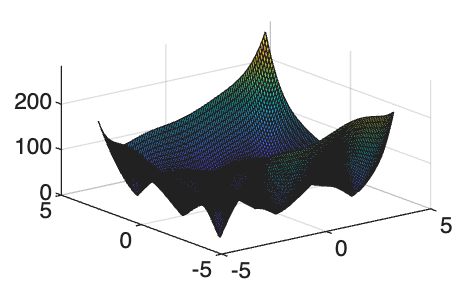

%fazer plot da funcao
funcao=@(x1,x2) ((x1.^2 + x2 - 11).^2 + (x1 + x2.^2 - 7).^2);
j1 =@(x1,x2)(4.*x1.^3+4.*x1.*x2-42.*x1+2.*x2.^2-14);
j2=@(x1,x2)(4.*x2.^3+4.*x1.*x2-26.*x2+2.*x1.^2-22);


x1 = linspace(-4,4,100);
x2 = linspace(-4,4,100);
[x1,x2] = meshgrid(x1,x2);
Z2 = sqrt(j1(x1,x2).^2+j2(x1,x2).^2);
surf(x1,x2,Z2)


surf(x1,x2,Z2)


figure; surf(x1,x2,Z2)

%a
%correr os pontos 
format long

[x1 x2 t iter] = Newton(-3.75758,-3.19192,10^(-6),100000)

x1 =   -3.779310253385251


x2 =   -3.283185991318091


t = "minimo"

iter =      4


format long

[x1 x2 t iter] = Newton(-3.0303,-0.040404,10^(-6),100000)

x1 =   -3.073025750764448


x2 =   -0.081353044287951


t = "pontodesela"

iter =      4


format long

[x1 x2 t iter] = Newton(-2.78788,3.27273,10^(-6),100000)

x1 =   -2.805118086925554


x2 =    3.131312518801965


t = "minimo"

iter =      4


format long

[x1 x2 t iter] = Newton(-0.121212,-1.0101,10^(-6),100000)

x1 =   -0.270844590736833


x2 =   -0.923038555982565


t = "maximo"

iter =      4


format long

[x1 x2 t iter] = Newton(0.121212,2.94949,10^(-6),100000)

x1 =    0.086677504555687


x2 =    2.884254701176355


t = "pontodesela"

iter =      4


format long

[x1 x2 t iter] = Newton(3.51515,0.121212,10^(-6),100000)

x1 =    3.385154183738056


x2 =    0.073851879892457


t = "pontodesela"

iter =      4


format long

[x1 x2 t iter] = Newton(3.0303,2.22222,10^(-6),100000)

x1 =    2.999999999999964


x2 =    2.000000000000164


t = "minimo"

iter =      5


format long

[x1 x2 t iter] = Newton(3.67677,-1.81818,10^(-6),100000)

x1 =    3.584428340340247


x2 =   -1.848126526966317


t = "minimo"

iter =      4


%b
format long

[x t iter] = Algoritmo1(-3.75758,-3.19192,10^(-6),100000)

x =   -3.779310253407118
  -3.283185991318342


t = "minimo"

iter =      5


format long

[x t iter] = Algoritmo1(-3.0303,-0.040404,10^(-6),100000)

x =   -3.073025750766575
  -0.081353044334032


t = "pontodesela"

iter =      5


format long

[x t iter] = Algoritmo1(-2.78788,3.27273,10^(-6),100000)

x =   -2.805118086962118
   3.131312518250827


t = "minimo"

iter =      6


format long

[x t iter] = Algoritmo1(-0.121212,-1.0101,10^(-6),100000)

x =   -0.270844589944776
  -0.923038556257487


t = "maximo"

iter =      6


format long

[x t iter] = Algoritmo1(0.121212,2.94949,10^(-6),100000)

x =    0.086677505328405
   2.884254701128080


t = "pontodesela"

iter =      5


format long

[x t iter] = Algoritmo1(3.51515,0.121212,10^(-6),100000)

x =    3.385154183608883
   0.073851879878458


t = "pontodesela"

iter =      6


format long

[x t iter] = Algoritmo1(3.0303,2.22222,10^(-6),100000)

x =    2.999999989050066
   1.999999996280237


t = "minimo"

iter =      6


format long

[x t iter] = Algoritmo1(3.67677,-1.81818,10^(-6),100000)

x =    3.584428340330818
  -1.848126526964540


t = "minimo"

iter =      6


%c
format long

[x t iter matriza] = Algoritmo1c(3.67677,-1.81818,10^(-12),100000)

x =    3.584428340330492
  -1.848126526964403


t = "minimo"

iter =      7


matriza =    3.587885130051509   3.584550557587261   3.584428542449246   3.584428353477064   3.584428340330818   3.584428340330492                   0
  -1.848734695105728  -1.848086990987076  -1.848128903592662  -1.848126609707172  -1.848126526964540  -1.848126526964403                   0



[x1 x2 t iter matrizn] = Newtonc(3.67677,-1.81818,10^(-12),100000)

x1 =    3.584428340330492


x2 =   -1.848126526964404


t = "minimo"

iter =      5


matrizn =    3.587885130051509   3.584433221950404   3.584428340340247   3.584428340330492                   0
  -1.848734695105728  -1.848127435329876  -1.848126526966317  -1.848126526964404                   0


%faz lista dos erros
xreal = [3.584428340330; -1.848126526964];

errosn = zeros(1, size(matrizn, 2));
for k = 1:size(matrizn, 2)
    errosn(k) = norm(matrizn(:, k) - xreal, 2);
end


p = [];
for k = 2:length(errosn)-1
    %casas decimais do format long
    if errosn(k+1) > 1e-15 && errosn(k) > 1e-15 && errosn(k-1) > 1e-15
        n = log(errosn(k+1)/errosn(k));
        d = log(errosn(k)/errosn(k-1));
        p(end+1) = n/d;
    end
end
p

p =    1.991526608905676   0.214624842819809 -10.511643415628336


C = [];

for k = 2:length(errosn)-1
    if errosn(k) > 1e-15
        % Usamos o p calculado para a iteração específica
        C(end+1) = errosn(k+1) / (errosn(k)^2);
    end
end
C

C = 1.0e+24 *

   0.000000000000000   0.000000000000006   9.966645291838836


xreal = [3.584428340330; -1.848126526964];


errosa = zeros(1, size(matriza, 2));
for k = 1:size(matriza, 2)
    errosa(k) = norm(matriza(:, k) - xreal, 2);
end


p = [];
for k = 2:length(errosa)-1
    %casas decimais do format long
    if errosa(k+1) > 1e-15 && errosa(k) > 1e-15 && errosa(k-1) > 1e-15
        n = log(errosa(k+1)/errosa(k));
        d = log(errosa(k)/errosa(k-1));
        p(end+1) = n/d;
    end
end

p

p =    1.205123156389310   0.840090733815790   3.390950710537257   0.038116682382554 -68.103481707602370


matrizn

matrizn =    3.587885130051509   3.584433221950404   3.584428340340247   3.584428340330492                   0
  -1.848734695105728  -1.848127435329876  -1.848126526966317  -1.848126526964404                   0


matriza

matriza =    3.587885130051509   3.584550557587261   3.584428542449246   3.584428353477064   3.584428340330818   3.584428340330492                   0
  -1.848734695105728  -1.848086990987076  -1.848128903592662  -1.848126609707172  -1.848126526964540  -1.848126526964403                   0


format long

[x t iter matriza] = Algoritmo1c(5,-4,10^(-12),100000)

x =    3.584428340330492
  -1.848126526964403


t = "minimo"

iter =     13


matriza =    4.039381278335852   3.755842324331360   3.591935857395215   3.554979096145361   3.564539340763417   3.580492942465617   3.584066633449686   3.584426327054252   3.584428334075593   3.584428340337000   3.584428340330492   3.584428340330492                   0
  -2.882567339319051  -2.467715582320536  -2.142232449071085  -1.977703900376640  -1.881202296299616  -1.848721208664994  -1.847446442646025  -1.848110802479818  -1.848126549747127  -1.848126526962659  -1.848126526964403  -1.848126526964403                   0



[x1 x2 t iter matrizn] = Newtonc(5,-4,10^(-12),100000)

x1 =    3.584428340330492


x2 =   -1.848126526964404


t = "minimo"

iter =      8


matrizn =    4.039381278335852   3.666575608281751   3.592770576210677   3.584842379040596   3.584429817265003   3.584428340349429   3.584428340330492                   0
  -2.882567339319051  -2.231305369914019  -1.927997392441299  -1.852700527919940  -1.848142857071141  -1.848126527173704  -1.848126526964404                   0


% (d)

clc
clear

eps = 1e-12;
k = 1000;
x0 = [4.0; -1.0];
xstar = [3.584428340330; -1.848126526964];

[x,t,iter,eA,eS,eP] = Algoritmo1d(x0(1),x0(2),eps,k,xstar);

x

x =    3.584428340330492
  -1.848126526964404


t

t = "minimo"

iter

iter =     15


eA

eA = 1.0e+02 *

   0.415857728860265   5.820304881637510   5.830937773525925   2.260672197865072   0.230991589309278   0.057957956610752   0.118933794247831   0.132518940369212   0.057973299226075   0.057974449530730   0.057969662879992   0.057974393777134   0.058756408652843   0.000070208609620   0.000000242414893


eS

eS = 1.0e+02 *

   0.277096583669197   5.812223869508562   1.914740666253267   1.184236459842283   0.227887666351241   0.052839171538852   0.118914321020250   0.132517516485921   0.020633485965414   0.022714496098716   0.005353122245662   0.000723672190223   0.019417327362054   0.000065748794294   0.000000128264365


eP

eP =   11.572398058958052   1.080359589925659   0.068036402921180   0.098859858692413   2.161854616094365   1.494969488687439   0.487973860844518   1.551772739183282   1.181627288350106   0.910774531159588   1.017442787170067   1.001526163491862   0.993437100033179   0.999511731389535   0.131912666201157


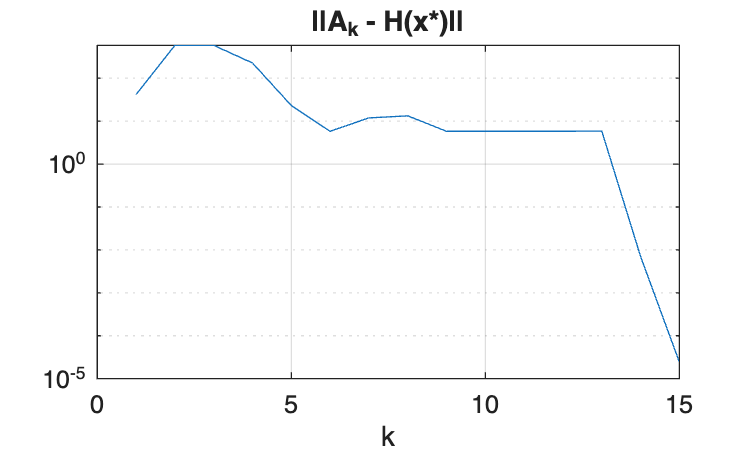


figure
semilogy(1:iter, eA)
title('||A_k - H(x*)||')
xlabel('k')
grid on

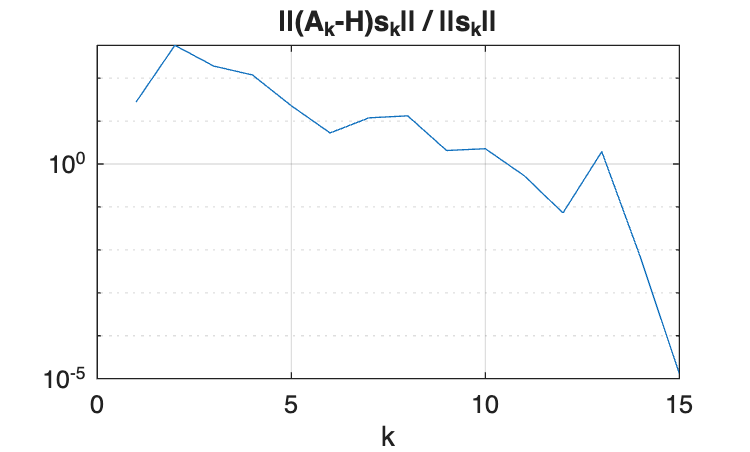

%saveas(gcf, '2d_eA.png')

figure
semilogy(1:iter, eS)
title('||(A_k-H)s_k|| / ||s_k||')
xlabel('k')
grid on

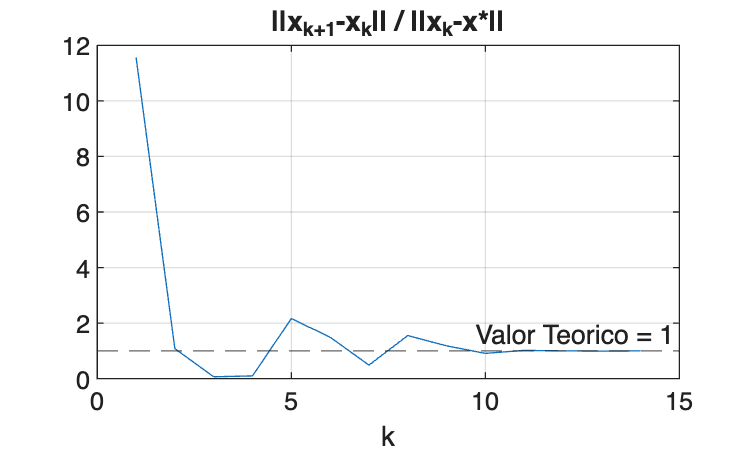

%saveas(gcf, '2d_eS.png')

eP_plot = eP(1:end-1);
figure
plot(eP_plot)
yline(1, '--', 'Valor Teorico = 1')
title('||x_{k+1}-x_k|| / ||x_k-x*||')
xlabel('k')
grid on

%saveas(gcf, '2d_eP.png')

% (e)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%555
format long 
x0 = [2.9;1.9];
z = [3;2];


h = @ (p,q) ([12.*p.^2+4.*q-42 4.*p+4.*q;4.*p+4.*q 12.*q.^2+4.*p-26]);
F = @ (p,q) ([4.*p.^3+4.*p.*q-42.*p+2.*q.^2-14;4.*q.^3+4.*p.*q-26.*q+2.*p.^2-22]);
G = @(x) -inv(h(x(1),x(2)))*F(x(1),x(2)) + x;

[xn matrizf] = metodopontofixo(10^-4, x0) % converge para valores proximos de (3,2)

xn =    2.999999999637001
   2.000000001524965


matrizf =    2.900000000000000   2.999999431343344   2.999999999637001
   1.900000000000000   2.000043151271737   2.000000001524965



% estimativa para o coeficiente assintotico do metodo do ponto fixo proposto
format long
xn1 = G(xn)

xn1 =      3
     2


norm(z - xn1)./norm(z - xn)

ans =      0




% Calcular o erro de cada iteração comparado com a solução z
errosf = zeros(1, size(matrizf, 2));
for k = 1:size(matrizf, 2)
    errosf(k) = norm(matrizf(:, k) - z, 2);
end

p = [];
for k = 2:length(errosf)-1
    % Evitar divisão por zero ou log de números muito pequenos
    if errosf(k+1) > 1e-15 && errosf(k) > 1e-15 && errosf(k-1) > 1e-15
        n = log(errosf(k+1)/errosf(k));
        d = log(errosf(k)/errosf(k-1));
        p(end+1) = n/d;
    end
end

p

p =    1.262928200022303



C = [];

for k = 2:length(errosf)-1
    if errosf(k) > 1e-15
        % Usamos o p calculado para a iteração específica
        C(end+1) = errosf(k+1) / (errosf(k)^2);
    end
end
C

C =    0.841715264544236



%c
format long


[x1 x2 t iter matrizn] = Newtonc(2.9,1.9,10^(-12),100000)

x1 =      3


x2 =      2


t = "minimo"

iter =      5


matrizn =    3.004056694332728   2.999999431343344   2.999999999637001   3.000000000000000                   0
   2.007403577759738   2.000043151271737   2.000000001524965   2.000000000000000                   0


[x t iter matriza] = Algoritmo1c(2.9,1.9,10^(-12),100000)

x =      3
     2


t = "minimo"

iter =      8


matriza =    3.004056694332728   3.000065809172458   2.999947012926197   2.999999536652905   3.000000000144828   3.000000000000000   3.000000000000000                   0
   2.007403577759738   1.999130413731559   2.000063704305410   2.000000117174411   2.000000000310577   2.000000000000004   2.000000000000000                   0



x0 = [2.9;1.9];

 [xn matrizf] = metodopontofixo(10^-12, x0)

xn =      3
     2


matrizf =    2.900000000000000   2.999999431343344   2.999999999637001   3.000000000000000   3.000000000000000
   1.900000000000000   2.000043151271737   2.000000001524965   2.000000000000000   2.000000000000000


format long
z = [3; 2];
x0 = [2.5; 2.5];

 [xn matrizf] = metodopontofixo(10^-12, x0)

xn =      3
     2


matrizf =    2.500000000000000   3.010131082748283   3.000056385720202   3.000000001588896   3.000000000000000   3.000000000000000
   2.500000000000000   1.998857816966880   1.999972357437251   1.999999999608355   2.000000000000000   2.000000000000000


%c
format long


[x1 x2 t iter matrizn] = Newtonc(3,1,10^(-12),100000)

x1 =      3


x2 =      2


t = "minimo"

iter =     12


matrizn =    3.656565656565657   3.331146494387605   3.562402993617629   3.269327277902042   2.883649412726076   2.945342066709576   2.993512781566484   2.999850702584363   2.999999921848770   2.999999999999979   3.000000000000000                   0
  -0.747474747474748   0.919932894744357  -0.834376292025080   1.422300113124151   2.719969730678047   2.219923793594033   2.029783453881536   2.000672379116431   2.000000354343626   2.000000000000098   2.000000000000000                   0


[x t iter matriza] = Algoritmo1c(3,1,10^(-12),100000)

x =    3.385154183607021
   0.073851879837750


t = "pontodesela"

iter =     12


matriza =    3.656565656565657   3.307999591862074   3.418887321478833   3.471901852440817   3.384672631447844   3.384977359332593   3.385109215702281   3.385154185923937   3.385154183607052   3.385154183607021   3.385154183607021                   0
  -0.747474747474748   0.069823415273741  -0.019456218126971  -0.234635964616225   0.079889657345485   0.073818614434842   0.073820982774480   0.073851888431832   0.073851879835895   0.073851879837749   0.073851879837750                   0



x0 = [3;1];

 [xn matrizf] = metodopontofixo(10^-12, x0)

xn =      3
     2


matrizf =    3.000000000000000   3.331146494387605   3.562402993617629   3.269327277902042   2.883649412726076   2.945342066709576   2.993512781566484   2.999850702584363   2.999999921848770   2.999999999999979   3.000000000000000
   1.000000000000000   0.919932894744357  -0.834376292025080   1.422300113124151   2.719969730678047   2.219923793594033   2.029783453881536   2.000672379116431   2.000000354343626   2.000000000000098   2.000000000000000
